Задаём константы и параметры, необходимые для моделирования решётки

clear all
nu = 8e4;
c = 335; %Скорость звука
optimal_d = 0.95*c/(2*nu); %Рассчёт оптимального расстояния между датчиками (коэффициент должен лежать в пределах от 0 до 1)
xn = [0, optimal_d, 2*optimal_d, 3*optimal_d, 4*optimal_d, 5*optimal_d, 6*optimal_d]; %Координаты микрофонов в МН с неэквидистантным расположением датчиков
rotate_D = 90; % Значение угла, на котором находится главный лепесток ДН

theta_arrival = 50; %Угол, с которого приходит сигнал

N = size(xn,2); %Количество элементов в массиве
w = 1/N; %Комплексный весовой коэффициент каждого элемента
phi_limits = [1,180]; %Границы ДН по азимутальному углу в градусах [от,до]
phi_step = 1; %Шаг изменения угла ДН по азимутальному углу

phi = phi_limits(1):1:phi_limits(2); %Массив со всеми исследуемыми углами
phi_c = cosd(phi); %Массив с косинусами всех исследуемых углов
phi_c = phi_c - cosd(rotate_D); %Учитываем желаемый угол поворота ДН

Добавим сигнал, который будет падать на микрофонную решётку

amp = 1;
lambda_s = c/nu;
t=(0:0.0000005:0.0001);
%s = amp*cos(2*pi*nu*t); %Через тригонометрическую функцию
s = exp(1j*2*pi*nu*t); %Через экспоненту
figure(1);
plot(t,s);

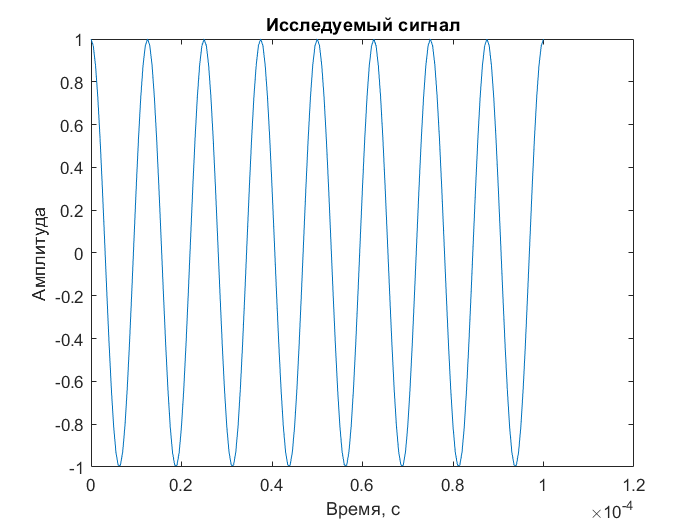

title("Исследуемый сигнал");
xlabel("Время, с");
ylabel("Амплитуда");

Сигналы, которые получают отдельные микрофоны

tau = -(xn/c)*sind(theta_arrival); %Временные задержки на каждом микрофоне
for i = 1:N
a_theta_zero(i,:) = exp(1j*2*pi*nu*tau(i)); %Тот самый стиринг-вектор, который мы получаем из сигналов микрофонов
end
%s_arr(4,:) = s*exp(1j*2*pi*xn(4)*sind(theta_zero)/lambda_s);
figure(2);
subplot(4,1,1);
plot(t,s*a_theta_zero(1,:));

title("Сигнал на 1м микрофоне");
subplot(4,1,2);
plot(t,s*a_theta_zero(2,:));

title("Сигнал на 2м микрофоне");
subplot(4,1,3);
plot(t,s*a_theta_zero(3,:));

title("Сигнал на 3м микрофоне");
subplot(4,1,4);
plot(t,s*a_theta_zero(4,:));

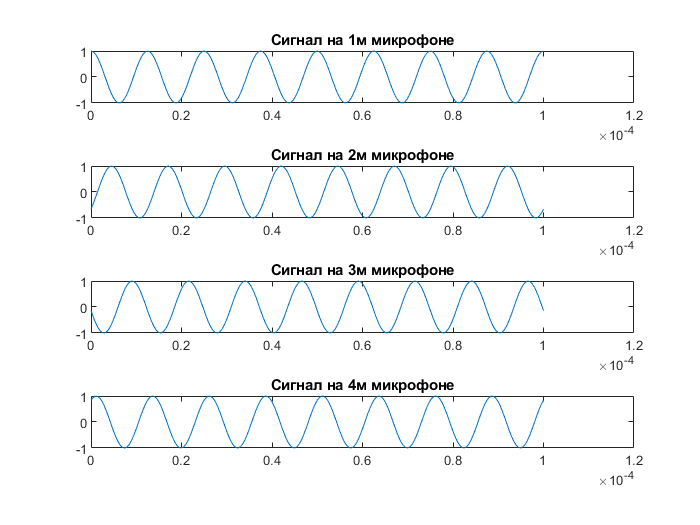

title("Сигнал на 4м микрофоне");

Direction-finding by **beamforming**

**Внимание! Углы отсчитываются относительно нормали к линии массива**

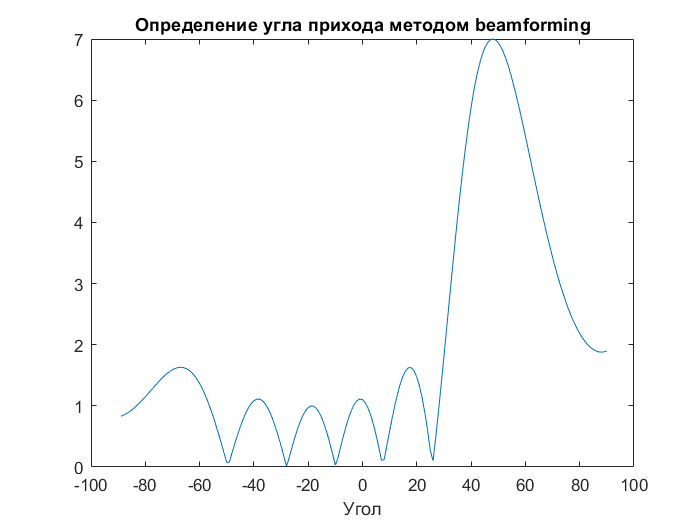

test_angle = -89:90; %Задаём диапазон "угадываемых углов"
for i = test_angle+abs(min(test_angle))+1 %Для каждого из них ищем массив задержек для заданного массива
tau(i,:) = -(xn/c)*sind(i-abs(min(test_angle))+1); %Массив временных задержек для каждого микрофона каждого "угадываемого" угла
end

for k = test_angle+abs(min(test_angle))+1
for i = 1:N
a_test(i,:) = exp(1j*2*pi*nu*tau(k,i)); %Стиринг-вектор сигнала, который мы пытаемся "угадать" или предсказать
end
M(k) = abs(a_test'*a_theta_zero); %Искомое произведение, пропорциональное вероятности правильного определения угла
end

figure(3);
plot(test_angle,M);
title("Определение угла прихода методом beamforming");
xlabel("Угол");